clear 
clc

theta_C=15*pi/180;
beta=15*pi/180;
P_z=0.55;
Z_arfada=0;
L_m=0.2;
C_x=0.1;  
C_y=0.4;
C1=[C_x,-C_y,0]; %Punto en el plano de union con la biela y<0
C2=[C_x,C_y,0]; %Punto en el plano de union con la biela y>0

D_x=0;
D_y=0.4; 
D_z=0.2;
D1=[D_x;-D_y;D_z]; %Punto del eje del motor y<0
D2=[D_x;D_y;D_z]; %Punto del eje del motor y>0
A=[0;0;0]; %Origen
B=[0;0;P_z+Z_arfada]; %Origen placa superior

theta1=pi/18; %angulo rotacion manivela


Ci1=PosCi(C1,theta_C,beta);
Ci1=Ci1(1:3,4);
Ci1=Ci1+B;

Ci2=PosCi(C2,theta_C,beta);
Ci2=Ci2(1:3,4);
Ci2=Ci2+B;



### Vectores

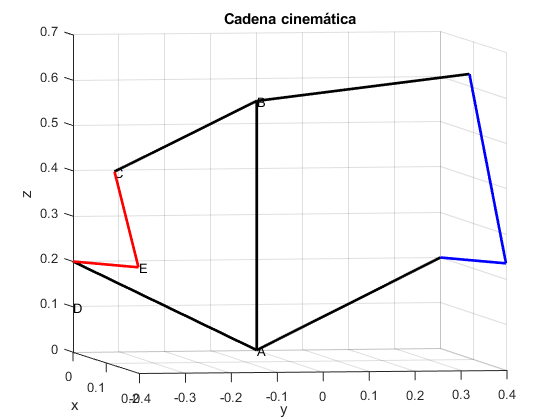



vABx=linspace(A(1),B(1),100);
vABy=linspace(A(2),B(2),100);
vABz=linspace(A(3),B(3),100);

vDA1x=linspace(A(1),D1(1),100);
vDA1y=linspace(A(2),D1(2),100);
vDA1z=linspace(A(3),D1(3),100);

vDA2x=linspace(A(1),D2(1),100);
vDA2y=linspace(A(2),D2(2),100);
vDA2z=linspace(A(3),D2(3),100);

vBC1x=linspace(B(1),Ci1(1),100);
vBC1y=linspace(B(2),Ci1(2),100);
vBC1z=linspace(B(3),Ci1(3),100);

vBC2x=linspace(B(1),Ci2(1),100);
vBC2y=linspace(B(2),Ci2(2),100);
vBC2z=linspace(B(3),Ci2(3),100);

Ei1=D1+(L_m.*[cos(theta1); 0; sin(theta1)]);
Ei2=D2+(L_m.*[cos(theta1); 0; sin(theta1)]);



vDE1x=linspace(D1(1),Ei1(1),100);
vDE1y=linspace(D1(2),Ei1(2),100);
vDE1z=linspace(D1(3),Ei1(3),100);

vDE2x=linspace(D2(1),Ei2(1),100);
vDE2y=linspace(D2(2),Ei2(2),100);
vDE2z=linspace(D2(3),Ei2(3),100);



vEC1x=linspace(Ei1(1),Ci1(1),100);
vEC1y=linspace(Ei1(2),Ci1(2),100);
vEC1z=linspace(Ei1(3),Ci1(3),100);

vEC2x=linspace(Ei2(1),Ci2(1),100);
vEC2y=linspace(Ei2(2),Ci2(2),100);
vEC2z=linspace(Ei2(3),Ci2(3),100);


%Cadena 1, y<0
plot3(vABx,vABy,vABz,'k',"LineWidth",2)
hold on
plot3(vDA1x,vDA1y,vDA1z,'k',"LineWidth",2)
plot3(vBC1x,vBC1y,vBC1z,'k',"LineWidth",2)
plot3(vDE1x,vDE1y,vDE1z,'r',"LineWidth",2)
plot3(vEC1x,vEC1y,vEC1z,'r',"LineWidth",2)

%Cadena 1, y>0
plot3(vDA2x,vDA2y,vDA2z,'k',"LineWidth",2)
plot3(vBC2x,vBC2y,vBC2z,'k',"LineWidth",2)
plot3(vDE2x,vDE2y,vDE2z,'b',"LineWidth",2)
plot3(vEC2x,vEC2y,vEC2z,'b',"LineWidth",2)
text(D1(1),D1(2),D1(3)-0.1,'D')
text(Ei1(1),Ei1(2),Ei1(3),'E')
text(0,0,0,'A')
text(B(1),B(2),B(3),'B')
text(Ci1(1),Ci1(2),Ci1(3),'C')
hold off
xlabel("x")
ylabel("y")
zlabel("z")
grid on
title("Cadena cinemática")

%DEi=(L_m.*[cos(theta1); 0; sin(theta1)]);
%EiCi=L_b*[sin(theta3)*cos(theta1+theta2);cos(theta3);sin(theta3)*sin(theta1+theta2)];


function [Pf] = PosCi(Pi,theta,beta) 
Pf=[1 0 0 0;0 cos(beta) -sin(beta) 0; 0 sin(beta) cos(beta) 0; 0 0 0 1]*[cos(theta) 0 sin(theta) 0;0 1 0 0; -sin(theta) 0 cos(theta) 0;0 0 0 1]*[1 0 0 Pi(1);0 1 0 Pi(2);0 0 1 Pi(3);0 0 0 1];
end